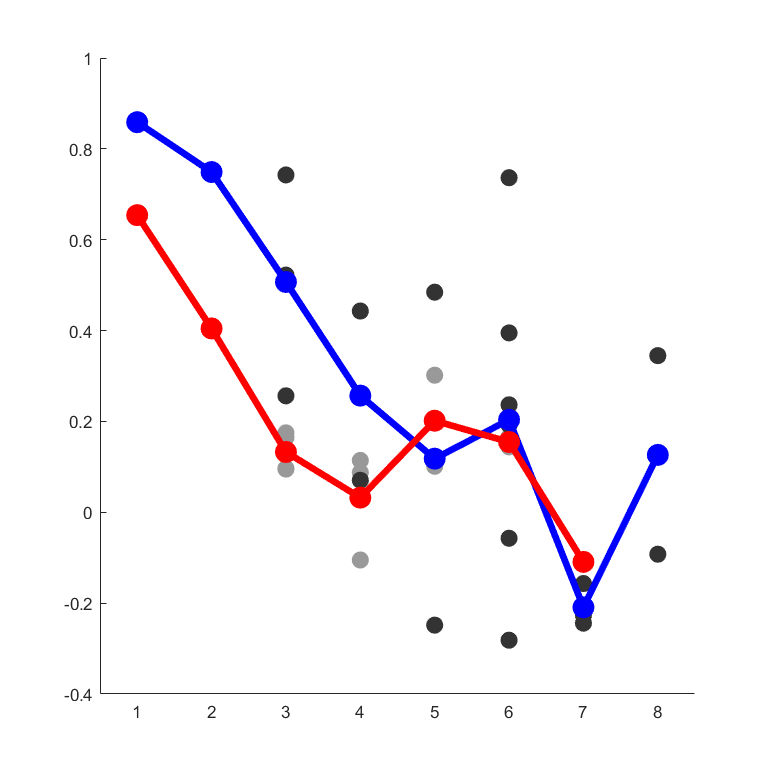

addpath(genpath('matlabfunctions'))
humans=load('Humans/alldata.mat');
monks=load('Monks/alldata.mat');

monks_cortdist=load('Monks/intermediate_files');
humans_cortdist=load('Humans/intermediate_files');
meanmonks_cortdist_rh=nanmean(monks_cortdist.avgdist_allsubjs_rh,2);
meanhumans_cortdist_rh=nanmean(humans_cortdist.avgdist_allsubjs_rh,2);
meanmonks_cortdist_lh=nanmean(monks_cortdist.avgdist_allsubjs_lh,2);
meanhumans_cortdist_lh=nanmean(humans_cortdist.avgdist_allsubjs_lh,2);

meanmonks_cortdist_rh1234=[];
meanmonks_cortdist_rh1234(1)=[meanmonks_cortdist_rh(1)+meanmonks_cortdist_rh(2)];
meanmonks_cortdist_rh1234(2)=[meanmonks_cortdist_rh(3)+meanmonks_cortdist_rh(4)]/2;
meanmonks_cortdist_rh1234(3)=[meanmonks_cortdist_rh(5)+meanmonks_cortdist_rh(6)]/2;
meanmonks_cortdist_rh1234(4)=[meanmonks_cortdist_rh(7)+meanmonks_cortdist_rh(8)]/2;
meanmonks_cortdist_rh1234(5)=[meanmonks_cortdist_rh(9)+meanmonks_cortdist_rh(10)]/2;
meanmonks_cortdist_rh1234=[meanmonks_cortdist_rh1234,meanmonks_cortdist_rh(11:end)'];

meanmonks_cortdist_lh1234=[];
meanmonks_cortdist_lh1234(1)=[meanmonks_cortdist_lh(1)+meanmonks_cortdist_lh(2)];
meanmonks_cortdist_lh1234(2)=[meanmonks_cortdist_lh(3)+meanmonks_cortdist_lh(4)]/2;
meanmonks_cortdist_lh1234(3)=[meanmonks_cortdist_lh(5)+meanmonks_cortdist_lh(6)]/2;
meanmonks_cortdist_lh1234(4)=[meanmonks_cortdist_lh(7)+meanmonks_cortdist_lh(8)]/2;
meanmonks_cortdist_lh1234(5)=[meanmonks_cortdist_lh(9)+meanmonks_cortdist_lh(10)]/2;
meanmonks_cortdist_lh1234=[meanmonks_cortdist_lh1234,meanmonks_cortdist_lh(11:end)'];

meanmonks_cortdist1234=[meanmonks_cortdist_lh1234+meanmonks_cortdist_lh1234]/2;


meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=[meanhumans_cortdist_rh(1)+meanhumans_cortdist_rh(2)];
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=[meanhumans_cortdist_lh(1)+meanhumans_cortdist_lh(2)];
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

human_labels =          {'V1', 'V2', 'V3','hV4','VO1','VO2','PHC1','PHC2', 'V3A','V3B','V7','LO1','LO2','TO1','TO2'}; 
human_areadistfromV1=    [0,     1,    2,   3,    4,   5,     6,      7,     3,    3,    4,   3,    4,    5,    6];
human_fellemanhierarchy=  [1,    2,    3,   5,    6,    6,    7,      7,     4,    4,    5,   5,     5,   5,    5]-1;

monk_labels =           {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
monk_areadistfromV1=      [0,    1,    2,   3,   4,   5,     6,    6,      6,      6,    3,    3,    4,    5,     6,     7,     8,     6,   7,    8,   7];
monk_fellemanhierarchy=   [1,    2,    3,   5,   5,   6,     6,    6,      7,      7,    4,    4,    5,     5,    6,     6,     6,     5,   6,    6,   5]-1;

monks_allareas=monks.V1_cat_corr1234;
humans_allareas=humans.V1_cat_corr1234;


for x = 1:max([monk_areadistfromV1,human_areadistfromV1])
    monk_meanareadist(x)=nanmean(monks_allareas(monk_areadistfromV1==x));
    human_meanareadist(x)=nanmean(humans_allareas(human_areadistfromV1==x));   
end

for x = 1:max([monk_fellemanhierarchy,human_fellemanhierarchy])
    monk_meanhierarchydist(x)=nanmean(monks_allareas(monk_fellemanhierarchy==x));
    human_meanhierarchydist(x)=nanmean(humans_allareas(human_fellemanhierarchy==x));   
end

stepsize=5;
maxrange=80;
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
human_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 80
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(5)=[human_meancortdist(4)+human_meancortdist(6)]/2;
human_meancortdist(7)=[human_meancortdist(6)+human_meancortdist(8)]/2;
human_meancortdist(14)=[human_meancortdist(13)+human_meancortdist(15)]/2;

figure(); 
hold on
plot(human_areadistfromV1(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',35)
plot(monk_areadistfromV1(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',35) 
plot(monk_meanareadist,'.-b','MarkerSize',45,'LineWidth',4)
plot(human_meanareadist,'.-r','MarkerSize',45,'LineWidth',4)
box off
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .4, .65]);
ax = gca;
ax.XAxis.TickLength = [0 0];
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])

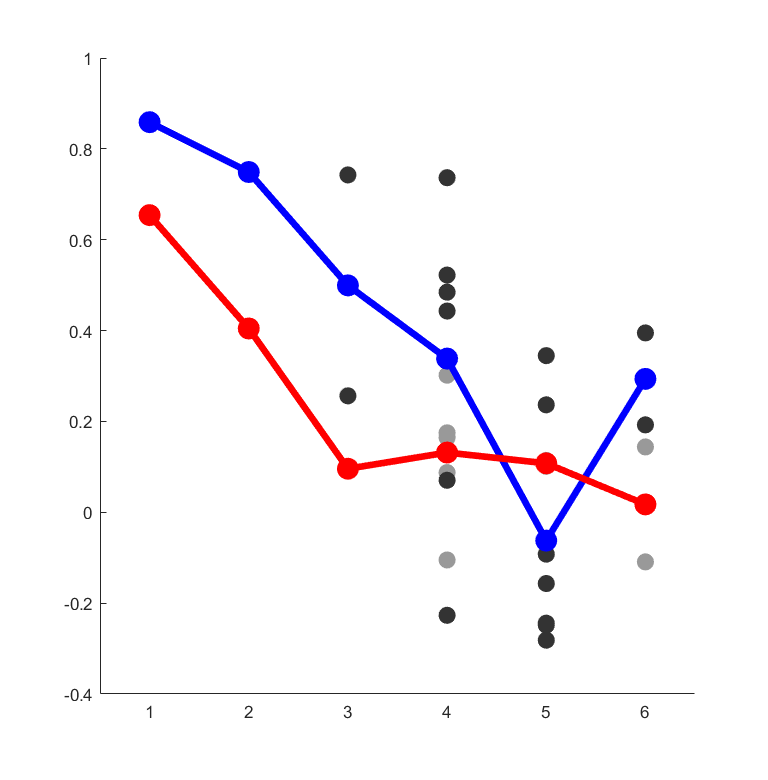

 
figure 
hold on
plot(human_fellemanhierarchy(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',35)
plot(monk_fellemanhierarchy(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',35) 
plot(monk_meanhierarchydist,'.-b','MarkerSize',45,'LineWidth',4)
plot(human_meanhierarchydist,'.-r','MarkerSize',45,'LineWidth',4)
box off
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .4, .65]);
ax = gca;
ax.XAxis.TickLength = [0 0];
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])

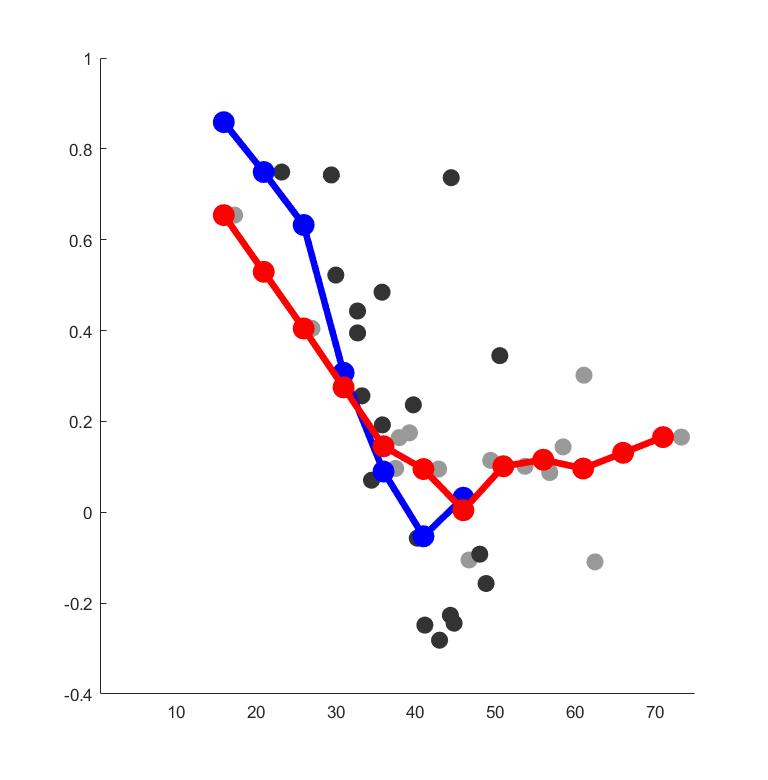


figure 
hold on
plot(meanhumans_cortdist1234(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',35)
plot(meanmonks_cortdist1234(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',35) 
plot(1:stepsize:maxrange,monk_meancortdist,'.-b','MarkerSize',45,'LineWidth',4)
plot(1:stepsize:maxrange,human_meancortdist,'.-r','MarkerSize',45,'LineWidth',4)
box off
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .4, .65]);
ax = gca;
ax.XAxis.TickLength = [0 0];
xlim([0.5 75])



figure 
hold on
plot(monks_allareas(2:3),humans_allareas(2:3),'.k','MarkerSize',80);
plot(monks_allareas(4),humans_allareas(4),'.k','MarkerSize',80);
plot(mean(monks_allareas(6:10)),mean(humans_allareas(5:8)),'.k','MarkerSize',80);
plot(mean(monks_allareas(18:end)),mean(humans_allareas(12:end)),'.k','MarkerSize',80);
plot(mean(monks_allareas(11:17)),mean(humans_allareas(9:11)),'.k','MarkerSize',80);

plot(monks_allareas(2:3),humans_allareas(2:3),'.b','MarkerSize',60);
plot(monks_allareas(4),humans_allareas(4),'.m','MarkerSize',60);
plot(mean(monks_allareas(6:10)),mean(humans_allareas(5:8)),'.r','MarkerSize',60);
plot(mean(monks_allareas(18:end)),mean(humans_allareas(12:end)),'.g','MarkerSize',60);
plot(mean(monks_allareas(11:17)),mean(humans_allareas(9:11)),'.','color',[1 .6 0],'MarkerSize',60);
xlim([0 1])
ylim([0 1])
plot([0 1],[0 1],'--k','LineWidth',6)
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .4, .65]);
ax = gca;
box off
ax.XAxis.TickLength = [0 0];

corr(nanmean(monks.normv1_combined,2),monk_areadistfromV1','Type','Spearman')

ans = -0.5835

corr(nanmean(humans.normv1_combined,2),human_areadistfromV1','Type','Spearman')

ans = -0.7954

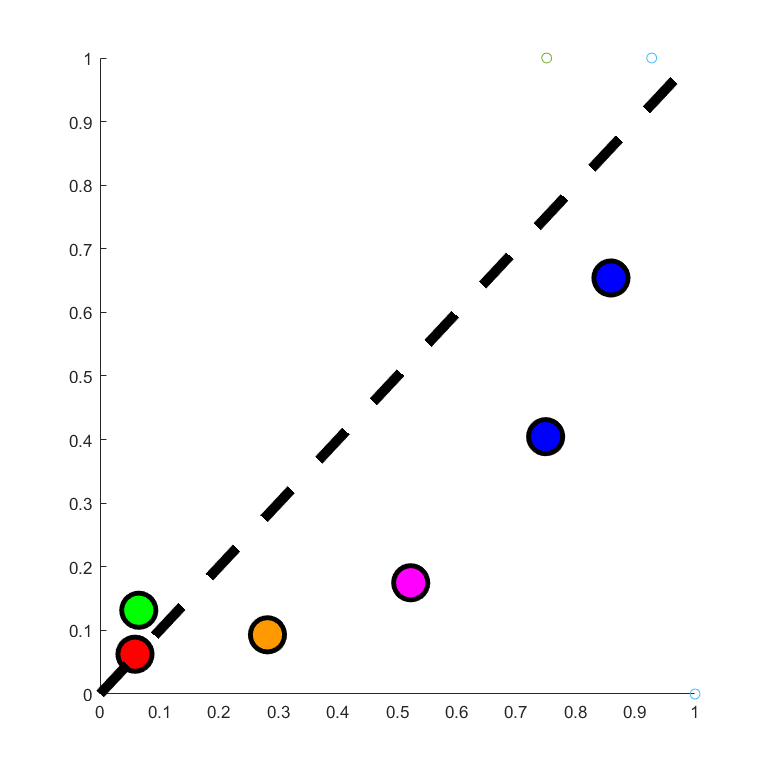


scatter(nanmean(monks.normv1_combined,2),monk_areadistfromV1')
scatter(nanmean(humans.normv1_combined,2),human_areadistfromV1')

mdeb_path = './Humans/mdeb/rois/';
mdeb_rois=Read_1D([mdeb_path,'allvisual-rh_fovfill.1D.dset']);

File ./Humans/mdeb/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


human.allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
human.allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','V7','LO1','LO2','TO1','TO2'};

meanhumansareas=nanmean(humans.normv1_combined,2);
mdeb_rois_area=mdeb_rois;
count=0;
for curr_roi = 1:length(human.allvisual_numbers)
    if curr_roi < 7
        if rem(curr_roi,2)
            count=count+1;
            mdeb_rois_area([mdeb_rois(:,2)==human.allvisual_numbers(curr_roi) | mdeb_rois(:,2)==human.allvisual_numbers(curr_roi+1)],2)=meanhumansareas(count);
            meanhumansareas(count)
        end
    else
        mdeb_rois_area(mdeb_rois(:,2)==human.allvisual_numbers(curr_roi),2)=meanhumansareas(curr_roi-3);
        end
end

ans = 1

ans = 0.9273

ans = 0.7347

dlmwrite([mdeb_path,'mdeb_rois_area_rh.1D.dset'],mdeb_rois_area)

corr_V1_cat = corr(humans.V1_surfacearea_cat', humans.retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
mdeb_rois_corr=mdeb_rois;
for curr_roi = 1:length(human.allvisual_numbers)
%     if curr_roi < 7
%         if rem(curr_roi,2)
%             mdeb_rois_corr([mdeb_rois(:,2)==human.allvisual_numbers(curr_roi) | mdeb_rois(:,2)==human.allvisual_numbers(curr_roi+1)],2)=corr_V1_cat(curr_roi);
%         end
%     else
        mdeb_rois_corr(mdeb_rois(:,2)==human.allvisual_numbers(curr_roi),2)=corr_V1_cat(curr_roi);
      %  end
end
dlmwrite([mdeb_path,'mdeb_rois_corr_rh.1D.dset'],mdeb_rois_corr)


baby4_path = './Monks/baby4/rois/';
baby4_rois=Read_1D([baby4_path,'allvisual-rh.1D.dset']);

File ./Monks/baby4/rois/allvisual-rh.1D.dset exists and will be read.
Reading file


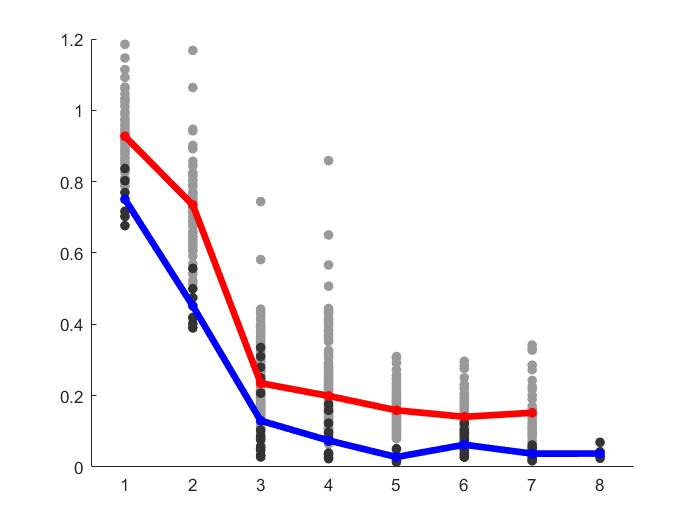

monk.allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,52,53,54,55,56,100,101,102,103];
monk.allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};       


meanmonksareas=nanmean(monks.normv1_combined,2);
baby4_rois_area=baby4_rois;
count=0;
for curr_roi = 1:length(monks.allvisual_numbers)
    if curr_roi < 11
        if rem(curr_roi,2)
            count=count+1;
            baby4_rois_area([baby4_rois(:,2)==monks.allvisual_numbers(curr_roi) | baby4_rois(:,2)==monk.allvisual_numbers(curr_roi+1)],2)=meanmonksareas(count);
        end
    else
        baby4_rois_area(baby4_rois(:,2)==monks.allvisual_numbers(curr_roi),2)=meanmonksareas(curr_roi-5);
        end
end
dlmwrite([baby4_path,'baby4_rois_area_rh.1D.dset'],baby4_rois_area)

corr_V1_cat = corr(monks.V1_surfacearea_cat', monks.retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
baby4_rois_corr=baby4_rois;
for curr_roi = 1:length(monk.allvisual_numbers)
%     if curr_roi < 7
%         if rem(curr_roi,2)
%             baby4_rois_corr([baby4_rois(:,2)==monk.allvisual_numbers(curr_roi) | baby4_rois(:,2)==monk.allvisual_numbers(curr_roi+1)],2)=corr_V1_cat(curr_roi);
%         end
%     else
        baby4_rois_corr(baby4_rois(:,2)==monk.allvisual_numbers(curr_roi),2)=corr_V1_cat(curr_roi);
      %  end
end
dlmwrite([baby4_path,'baby4_rois_corr_rh.1D.dset'],baby4_rois_corr)


meanmonksareas=nanmean(monks.normv1_combined,2);
baby4_rois_area=baby4_rois;
count=0;
for curr_roi = 1:length(monks.allvisual_numbers)
    if curr_roi < 11
        if rem(curr_roi,2)
            count=count+1;
            baby4_rois_area([baby4_rois(:,2)==monks.allvisual_numbers(curr_roi) | baby4_rois(:,2)==monk.allvisual_numbers(curr_roi+1)],2)=monk_areadistfromV1(count)+1;
        end
    else
        baby4_rois_area(baby4_rois(:,2)==monks.allvisual_numbers(curr_roi),2)=monk_areadistfromV1(curr_roi-5)+1;
        end
end
dlmwrite([baby4_path,'baby4_rois_areabetweenV1_rh.1D.dset'],baby4_rois_area)


monk_labels = {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};

monk_fellemanhierarchy=[1, 2, 3, 5, 5.5, 5.5, 6, 6, 7, 7, 4, 5.5, 5, 5, 6, 6, 6, 5, 6, 6, 5];
meanmonksareas=nanmean(monks.normv1_combined,2);
baby4_rois_area=baby4_rois;
count=0;
for curr_roi = 1:length(monks.allvisual_numbers)
    if curr_roi < 11
        if rem(curr_roi,2)
            count=count+1;
            baby4_rois_area([baby4_rois(:,2)==monks.allvisual_numbers(curr_roi) | baby4_rois(:,2)==monk.allvisual_numbers(curr_roi+1)],2)=monk_fellemanhierarchy(count);
        end
    else
        baby4_rois_area(baby4_rois(:,2)==monks.allvisual_numbers(curr_roi),2)=monk_fellemanhierarchy(curr_roi-5);
        end
end
dlmwrite([baby4_path,'baby4_rois_fellemanhierarchy_rh.1D.dset'],baby4_rois_area)


monks_allareas=nanmean(monks.normv1_combined,2);
humans_allareas=nanmean(humans.normv1_combined,2);

monk_areadistfromV1_indiv=repmat(monk_areadistfromV1',[1 size(monks.normv1_combined,2)]);
human_areadistfromV1_indiv=repmat(human_areadistfromV1',[1 size(humans.normv1_combined,2)]);

for x = 1:max(monk_areadistfromV1)
    monk_meanareadist(x)=nanmean(monks_allareas(monk_areadistfromV1==x));
    human_meanareadist(x)=nanmean(humans_allareas(human_areadistfromV1==x));
    
end

monk_dist1=monks.normv1_combined(monk_areadistfromV1==1,:); monk_dist1=monk_dist1(:);
monk_dist2=monks.normv1_combined(monk_areadistfromV1==2,:); monk_dist2=monk_dist2(:);
monk_dist3=monks.normv1_combined(monk_areadistfromV1==3,:); monk_dist3=monk_dist3(:);
monk_dist4=monks.normv1_combined(monk_areadistfromV1==4,:); monk_dist4=monk_dist4(:);
monk_dist5=monks.normv1_combined(monk_areadistfromV1==5,:); monk_dist5=monk_dist5(:);
monk_dist6=monks.normv1_combined(monk_areadistfromV1==6,:); monk_dist6=monk_dist6(:);
monk_dist7=monks.normv1_combined(monk_areadistfromV1==7,:); monk_dist7=monk_dist7(:);
monk_dist8=monks.normv1_combined(monk_areadistfromV1==8,:); monk_dist8=monk_dist8(:);

monk_alldist=nan(2000,7);
monk_alldist(1:length(monk_dist1),1)=monk_dist1;
monk_alldist(1:length(monk_dist2),2)=monk_dist2;
monk_alldist(1:length(monk_dist3),3)=monk_dist3;
monk_alldist(1:length(monk_dist4),4)=monk_dist4;
monk_alldist(1:length(monk_dist5),5)=monk_dist5;
monk_alldist(1:length(monk_dist6),6)=monk_dist6;
monk_alldist(1:length(monk_dist7),7)=monk_dist7;
monk_alldist(1:length(monk_dist8),8)=monk_dist8;

human_dist1=humans.normv1_combined(human_areadistfromV1==1,:); human_dist1=human_dist1(:);
human_dist2=humans.normv1_combined(human_areadistfromV1==2,:); human_dist2=human_dist2(:);
human_dist3=humans.normv1_combined(human_areadistfromV1==3,:); human_dist3=human_dist3(:);
human_dist4=humans.normv1_combined(human_areadistfromV1==4,:); human_dist4=human_dist4(:);
human_dist5=humans.normv1_combined(human_areadistfromV1==5,:); human_dist5=human_dist5(:);
human_dist6=humans.normv1_combined(human_areadistfromV1==6,:); human_dist6=human_dist6(:);
human_dist7=humans.normv1_combined(human_areadistfromV1==7,:); human_dist7=human_dist7(:);

human_alldist=nan(2000,7);
human_alldist(1:length(human_dist1),1)=human_dist1;
human_alldist(1:length(human_dist2),2)=human_dist2;
human_alldist(1:length(human_dist3),3)=human_dist3;
human_alldist(1:length(human_dist4),4)=human_dist4;
human_alldist(1:length(human_dist5),5)=human_dist5;
human_alldist(1:length(human_dist6),6)=human_dist6;
human_alldist(1:length(human_dist7),7)=human_dist7;


figure 
hold on
plot(human_areadistfromV1_indiv(2:end,:),humans.normv1_combined(2:end,:),'.','color',[.6 .6 .6],'MarkerSize',20)
plot(monk_areadistfromV1_indiv(2:end,:),monks.normv1_combined(2:end,:),'.','color',[.2 .2 .2],'MarkerSize',20) 
plot(monk_meanareadist,'.-b','MarkerSize',20,'LineWidth',4)
plot(human_meanareadist,'.-r','MarkerSize',20,'LineWidth',4)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
xlim([0.5 8.5])